clear;

lambda = 1.700; % um
img_depth = 999; 
per_grid = 5e-3; % sampling interval
time_window = 10*per_grid;
dt = time_window/img_depth; 

y_ac = readmatrix('voltage_all.xlsx','Sheet',1,'Range','A:A');
y_bg = readmatrix('bg.xlsx','Sheet',1,'Range','A:A');
y_bg = mean(y_bg);

% singal after subtracting bg 
y = y_ac - y_bg;

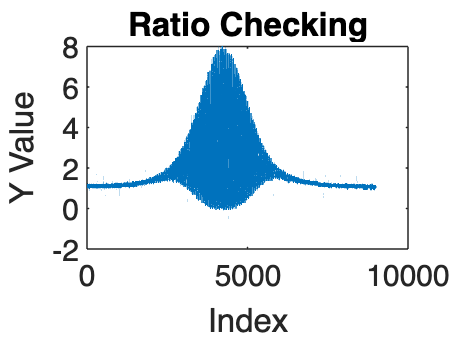

% check the ratio (1:8)
y_check = y/(max(y)/8);

t = 1:length(y);

plot(t,y_check);
xlabel('Index');    
ylabel('Y Value');  
title('Ratio Checking');  


base = mean(y_check(1:200)); % find the best gain 

%
y_check = y / (max(y) / 8);
t = 1:length(y);


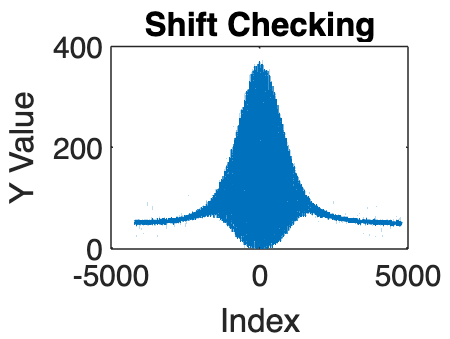

% Shift time axis so that t=0 at signal max
[max_value,max_index] = max(y);
t = t - max_index;

% Plot the shift
plot(t,y);
xlabel('Index');    
ylabel('Y Value');  
title('Shift Checking');  

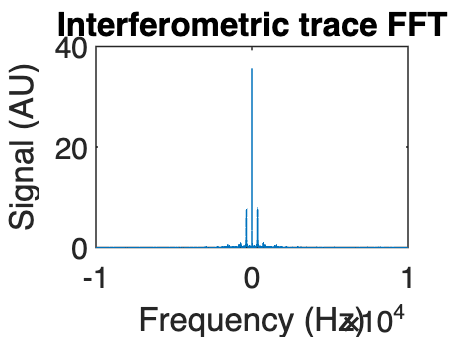

% Compute the FFT of the Interferometric AC trace

f = linspace(-1/2/dt,1/2/dt,length(t));
y_fft = ifftshift(fft(fftshift(y)))*dt;
y_fft_am = abs(y_fft);

% plot the FFT of signals
plot(f,y_fft_am);
xlabel('Frequency (Hz)');    
ylabel('Signal (AU)');  
title('Interferometric trace FFT');  

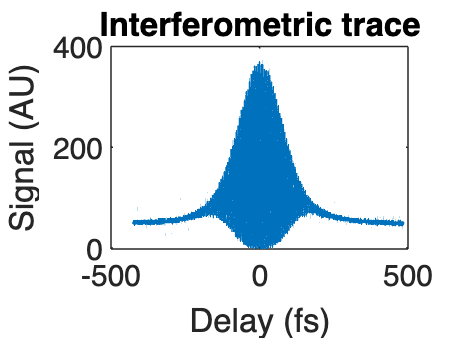


% find the fundamental frequency
peaks_index = [0;(y_fft_am(2:end)-y_fft_am(1:end-1)>0)].*[(y_fft_am(1:end-1)-y_fft_am(2:end)>0);0];
[~,I] = sort(y_fft_am.*peaks_index,'descend');
f_1 = (abs(f(I(2)))+abs(f(I(3))))/2; %[Hz]

% convert the time axis to optical delay
T = 1/f_1; %[s] fringe period
t = t*dt;  % time axis
delay = t*f_1*lambda/0.3; % [um] optical delay

% plot along with optical delay 
plot(delay,y);
xlabel('Delay (fs)');    
ylabel('Signal (AU)');  
title('Interferometric trace');  

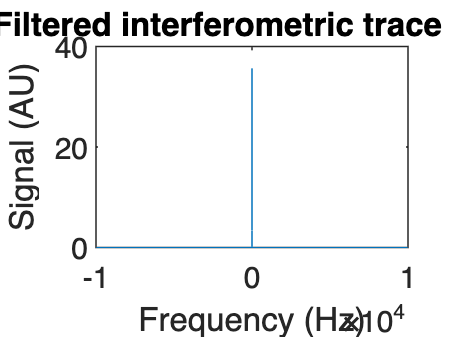

% Filter out the fringes
y_fft_filter = y_fft .* (abs(f) < f_1/50)';
%y_fft_filter = y_fft .* (abs(f) < 1*f_1)';

plot(f,abs(y_fft_filter));
xlabel('Frequency (Hz)');    
ylabel('Signal (AU)');  
title('Filtered interferometric trace FFT');  

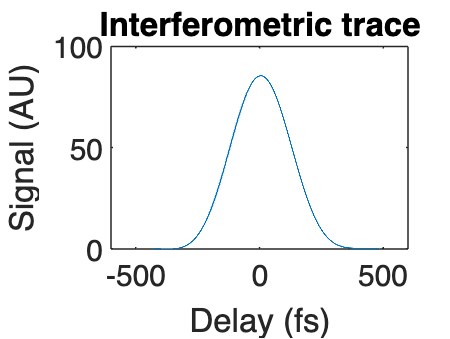

% Inverse FFT to get the intensity autocorrelation with background
I_AC = fftshift(ifft(ifftshift(y_fft_filter)))/dt;
I_AC = abs(I_AC);

% remove bg
bg = (sum(I_AC(1:5)) + sum(I_AC(end-4:end)))/10;
I_AC_bgoff = I_AC - bg;

plot(delay,I_AC_bgoff);
xlabel('Delay (fs)');    
ylabel('Signal (AU)'); 
xlim([-600,600])
title('Interferometric trace');  

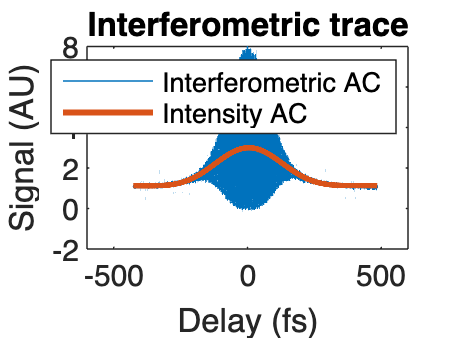

% draw the IAC
plot(delay,y_check);
xlabel('Delay (fs)');    
ylabel('Signal (AU)'); 
xlim([-600,600])
title('Interferometric trace');  

hold on
plot(delay,I_AC/(max(I_AC)/3),LineWidth=2);
legend('Interferometric AC','Intensity AC')

% calculate the FWHM of the intensity AC trace

tau_ac = fwhm(delay, I_AC_bgoff);  % [fs] BG free intensity AC FWHM
tau_gauss = tau_ac / sqrt(2);  % Pulse width assuming Gaussian shape
tau_sec = tau_ac / 1.543;  % Pulse width assuming sec^2 shape
disp(' ')

disp(['bg-free Intensity AC FWHM: ', num2str(tau_ac), ' fs'])

bg-free Intensity AC FWHM: 283.7086 fs


disp(['Gaussian pulse FWHM: ', num2str(tau_gauss), ' fs'])

Gaussian pulse FWHM: 200.6123 fs


disp(['Sech^2 pulse FWHM: ', num2str(tau_sec), ' fs'])

Sech^2 pulse FWHM: 183.8682 fs
